% process auto center offline simply

timeOffset = nan;
% load('/Users/sam/analysis/cellData/051216Ac4.mat')
% sessionId = 201651215217;

% load('/Users/sam/analysis/cellData/032416Ac9.mat')
% sessionId = 2016324173256;

% load('/Users/sam/analysis/cellData/060216Ac2.mat')
% sessionId = 2016512181624;

% load('/Users/sam/analysis/cellData/033016Bc8.mat')
% sessionId = 201633020044;

% load('/Users/sam/analysis/cellData/010716Ac4.mat') % WC ON
% sessionId = 1;

% load('/Users/sam/analysis/cellData/121616Ac7.mat')
% sessionId = 2016121616210;
% timeOffset = 0.3;

% load('/Users/sam/analysis/cellData/081517Ac3.mat')
% sessionId = {'2017815142854','2017815143647'};
% sessionId = 2017815142854; % on ex
% sessionId = 2017815143647; % off ex
% sessionId = 2017815152043; % on in
% timeOffset = 0.09;
% sessionId = 201781515724; % off in

% load('/Users/sam/analysis/cellData/101917Ac1.mat') % Iclamp on off
% sessionId = '20171019132525';

% load('/Users/sam/analysis/cellData/110917Ac8.mat') % big ex in
% sessionId = 1;

% load('/Users/sam/analysis/cellData/011718Ac1.mat') % HD2 CC
% sessionId = {'201811712578','2018117131112'};

% load('/Users/sam/analysis/cellData/011718Ac4.mat') % UHD use min response mode to toss noise
% sessionId = {'201811716347','20181171609'};


% load('/Users/sam/analysis/cellData/012418Bc3.mat')
% sessionId = {'2018124161454','201812416623'};

% load('/Users/sam/analysis/cellData/013118Ac24.mat')
% sessionId = {'201813117312','201813117151'};
% timeOffset = .39;


% load('/Users/sam/analysis/cellData/012418Bc2.mat')
% sessionId = {'2018124143353','201812414403'};
% sessionId = {'2018124143353'};
% sessionId = {'201812414403'};


% load('/Users/sam/analysis/cellData/021318Ac10.mat')
% % 201821317324 % -60 and 20
% % 201821317473 % -38 and -5
% % 201821318150 % -75 and 35
% % 2018213181637 % -50 and 10
% sessionId = {'201821318150'};
% timeOffset = .05;

% load('/Users/sam/analysis/cellData/021618Ac8.mat') % good Fmon vclamp offset
% sessionId = {'2018216181428'};
% timeOffset = .06;


% load('/Users/sam/analysis/cellData/021618Ac3.mat') % good Fmon vclamp offset
% sessionId = {'2018216144613'};
% timeOffset = .06;


% load('/Users/sam/analysis/cellData/022118Ac1.mat') % HD1 vclamp offset
% sessionId = {'2018221143242'};

% load('/Users/sam/analysis/cellData/022118Ac6.mat') % Fmon vclamp, weak signals though
% sessionId = {'2018221174338'};
% timeOffset = .09;

% load('/Users/sam/analysis/cellData/022118Ac5.mat') % Fmon vclamp, solid ON
% sessionId = {'201822116948'};
% timeOffset = .05;



% process

epochData = cell(1);
ei = 1;
for i = 1:length(cellData.epochs)
    epoch = cellData.epochs(i);
    if ~isnan(timeOffset)
        epoch.attributes('timeOffset') = timeOffset;
    end
    sid = epoch.get('sessionId');
    protocolVersion = epoch.get('protocolVersion');
    
    matched = 0;
    
    if iscell(sessionId)
        for a = 1:length(sessionId)
            if strcmp(sid, num2str(sessionId{a}))
                matched = 1;
            end
        end
        
    else 
        
        if sid == sessionId | strcmp(sid, num2str(sessionId))
            matched = 1;
        end
    end
    
    if matched
%         if epoch.get('presentationId') > 2
%             continue
%         end
        sd = ShapeData(epoch, 'offline');
        epochData{ei, 1} = sd;
        ei = 1 + ei;
%         epoch.attributes('timeOffset')

    end
end

Starting ShapeData with channel Amplifier_Ch1
Starting ShapeData with channel Amplifier_Ch1
Starting ShapeData with channel Amplifier_Ch1
Starting ShapeData with channel Amplifier_Ch1



processOptions = struct;
processOptions.temporalBufferSize = [.05, .3];
processOptions.repeatCombinationMode = 'median';

if length(epochData{1}) > 0 %#ok<ISMT>
    % analyze shapedata
    analysisData = processShapeData(epochData, processOptions);
    disp('analysis done');
else
    disp('no epochs found');
    return
end

analysis done


plotShapeData(analysisData, 'printParameters');

num positions: 55
num values: 2
num repeats: 3
holding voltages: -60
holding voltages: 20
holding voltages: -60
holding voltages: 20
             numEpochs: 4
             epochData: {4×1 cell}
        positionOffset: [0 0]
         spotTotalTime: 0.4500
            spotOnTime: 0.2500
            sampleRate: 1000
             positions: [55×2 double]
          observations: [648×14 double]
    observationColumns: {1×14 cell}
            timeOffset: 0.0600
     validSearchResult: 1
             sampleSet: [150×1 double]

  ShapeData with properties:

                        sessionId: '201822116948'
                   presentationId: 4
                        epochMode: 'flashingSpots'
                          ampMode: 'Whole cell'
                       ampVoltage: 20
                       sampleRate: 1000
                          preTime: 0.2500
                         stimTime: 1000
                   positionOffse

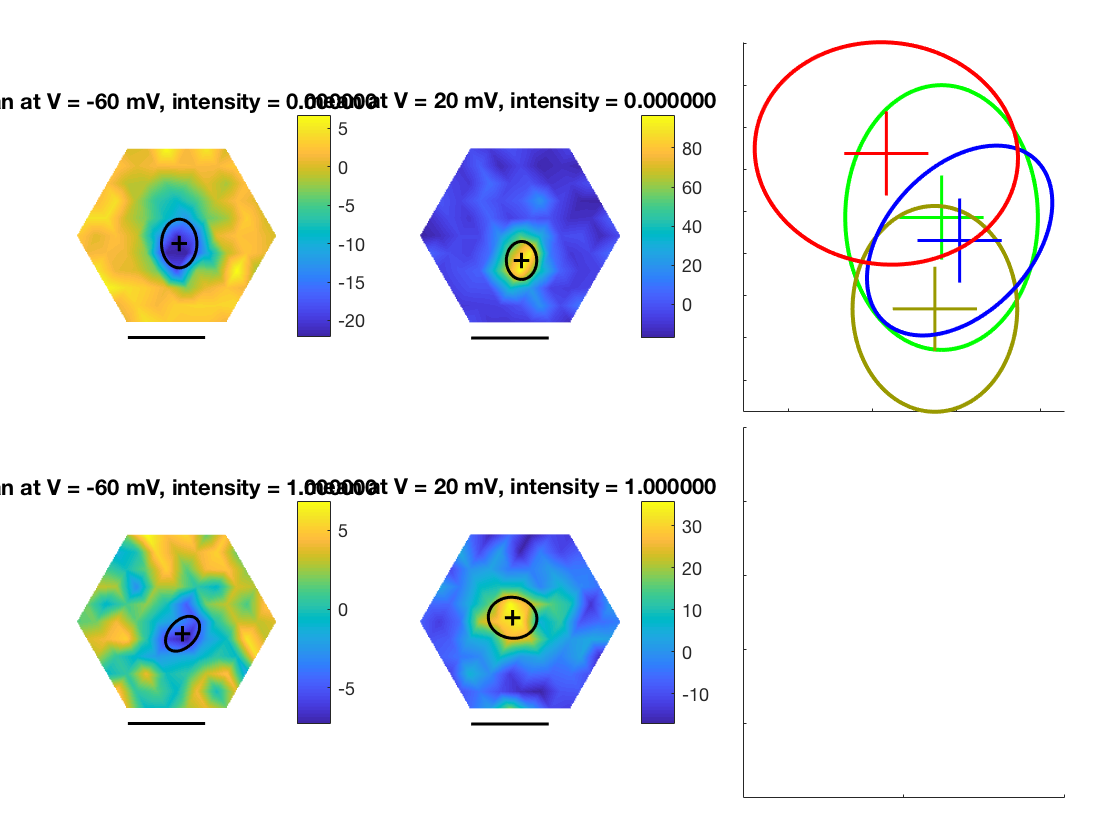

gaussian fit center: 16 um, -21 um
gaussian fit center: 21 um, -27 um
gaussian fit center: 15 um, -43 um
gaussian fit center: 3 um, -6 um


figure(10);clf;
plotShapeData(analysisData, 'plotSpatial_mean');

gaussian fit center: 16 um, -11 um
gaussian fit center: -2 um, -15 um
gaussian fit center: 29 um, 16 um
gaussian fit center: -18 um, 5 um


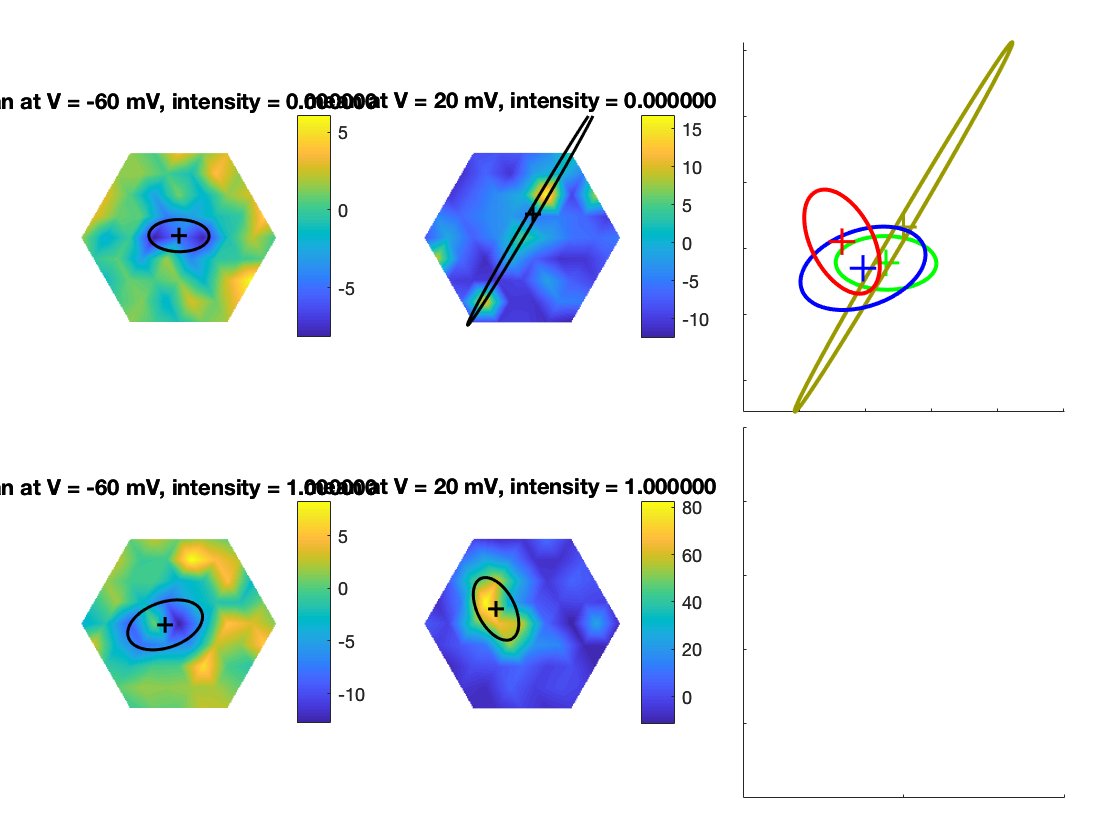


options = struct();

options.displayGaussianFits = 1;
plotShapeData(analysisData, 'plotSpatial_mean', options);

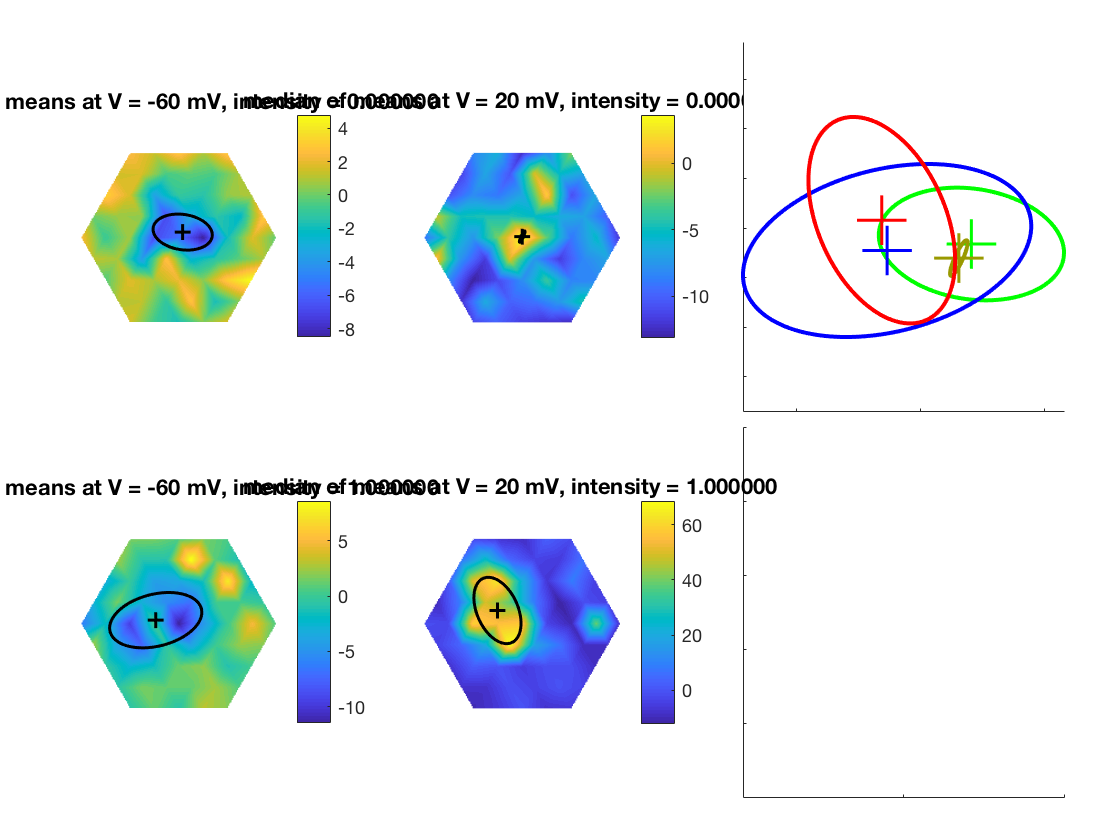

gaussian fit center: 20 um, -6 um
gaussian fit center: -14 um, -9 um
gaussian fit center: 15 um, -12 um
gaussian fit center: -16 um, 3 um


figure(10);clf;
plotShapeData(analysisData, 'plotSpatial_median');

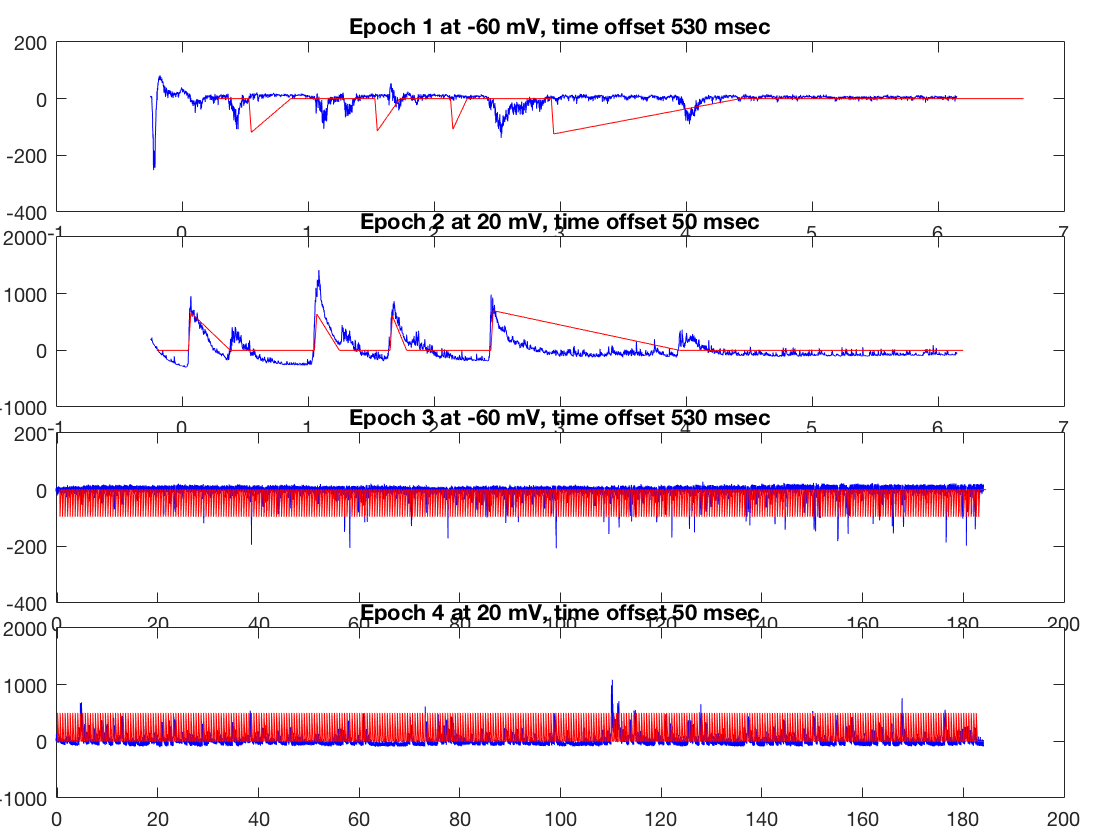

figure(11);clf;
plotShapeData(analysisData, 'temporalResponses');

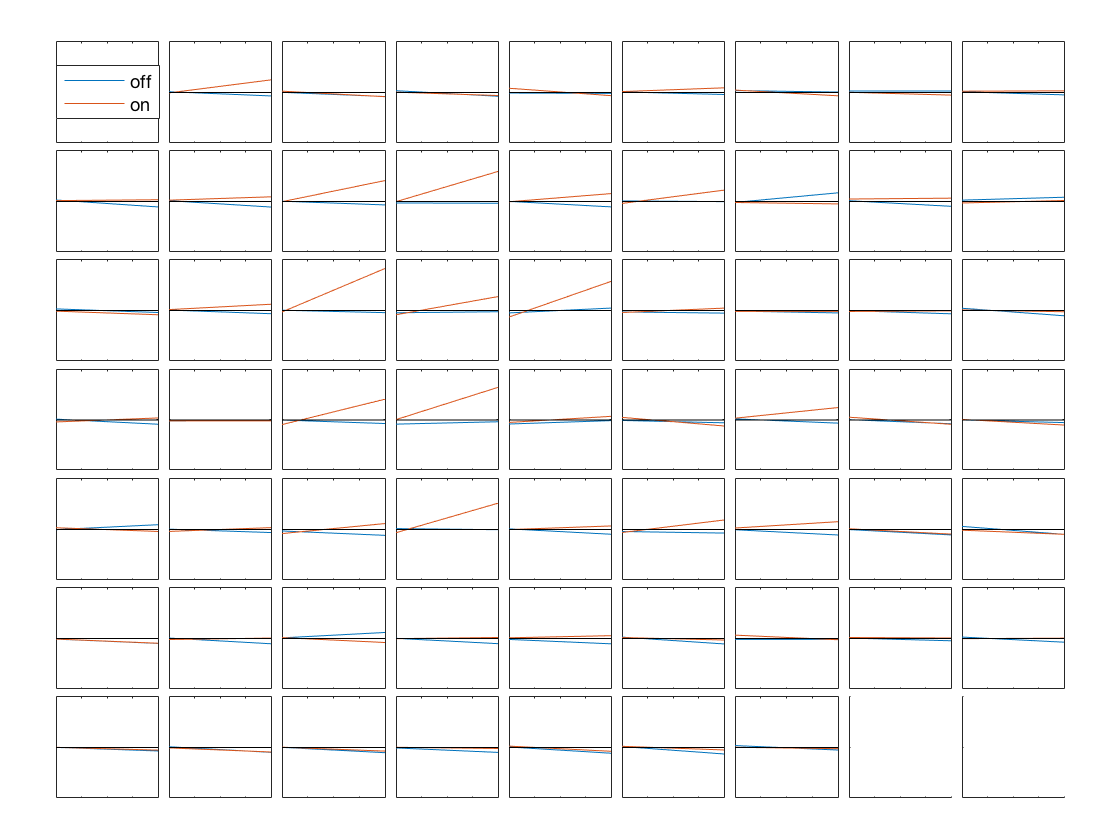

figure(12);clf;
plotShapeData(analysisData, 'currentVoltage');

## new plots

gaussian fit center: -5 um, -1 um
gaussian fit center: -2 um, 27 um
Spatial offset = 31.0 um, avg sigma2 = 33.0, ratio = 0.94, sessionId 50
Spatial offset = 48.0 um, avg sigma2 = 49.0, ratio = 56.00, sessionId 50
Spatial offset = 50.0 um, avg sigma2 = 49.0, ratio = 49.00, sessionId 54
Spatial offset = 57.0 um, avg sigma2 = 52.0, ratio = 56.00, sessionId   Columns 1 through 3

    'amplitude'    'angle'    'centerX'

  Columns 4 through 6

    'centerY'    'sigma2X'    'sigma2Y'

  Columns 1 through 4

   21.8959    1.2283   -5.1604   -1.0440

  Columns 5 through 6

   22.9629   52.1082

  Columns 1 through 4

  316.0188    0.5948   -2.2094   27.0000

  Columns 5 through 6

   25.3204   31.7628



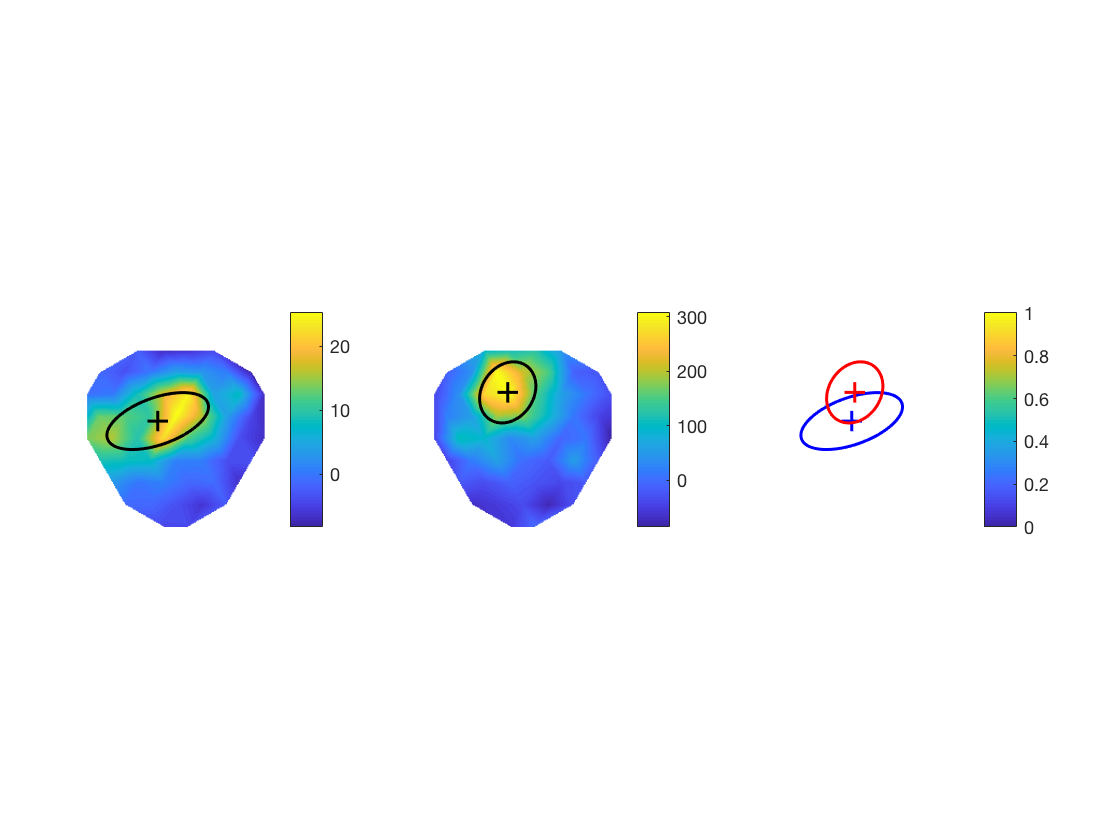

figure(13);clf; plotShapeData(analysisData, 'spatialOffset');

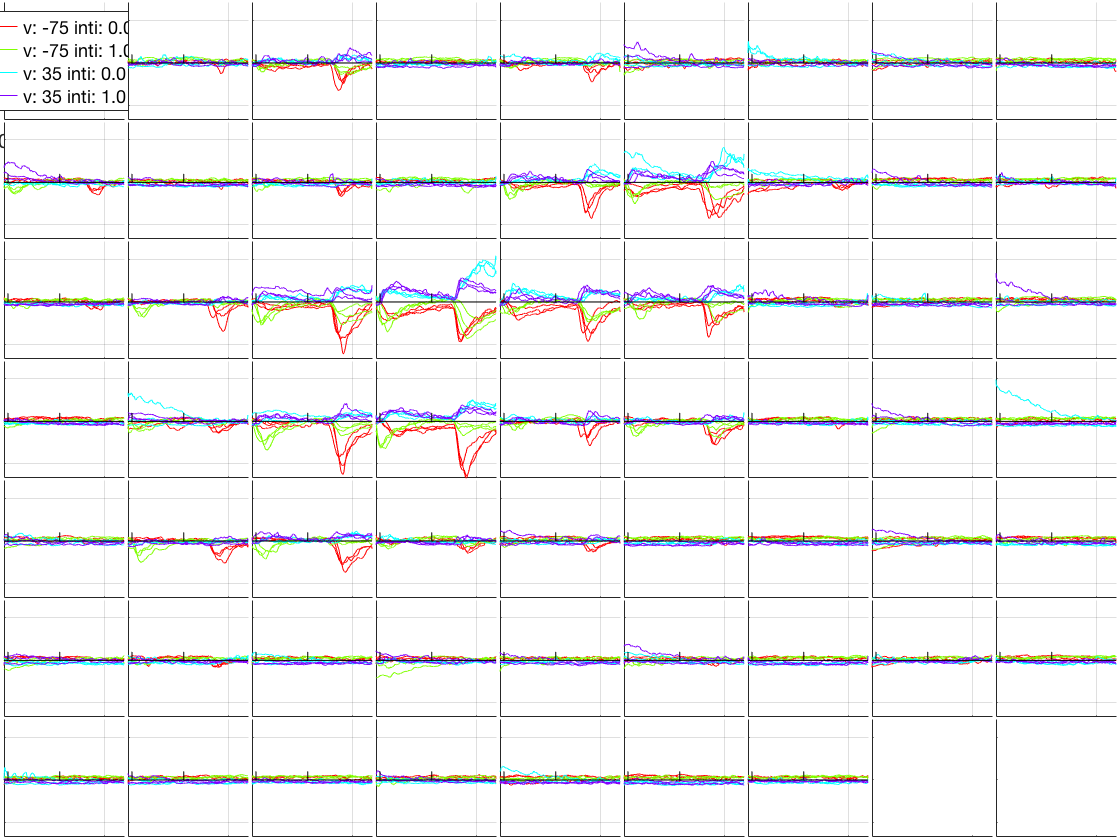

figure(15);clf;
plotShapeData(analysisData, 'responsesByPosition');

figure(11);clf; plotShapeData(analysisData, 'temporalComponents');

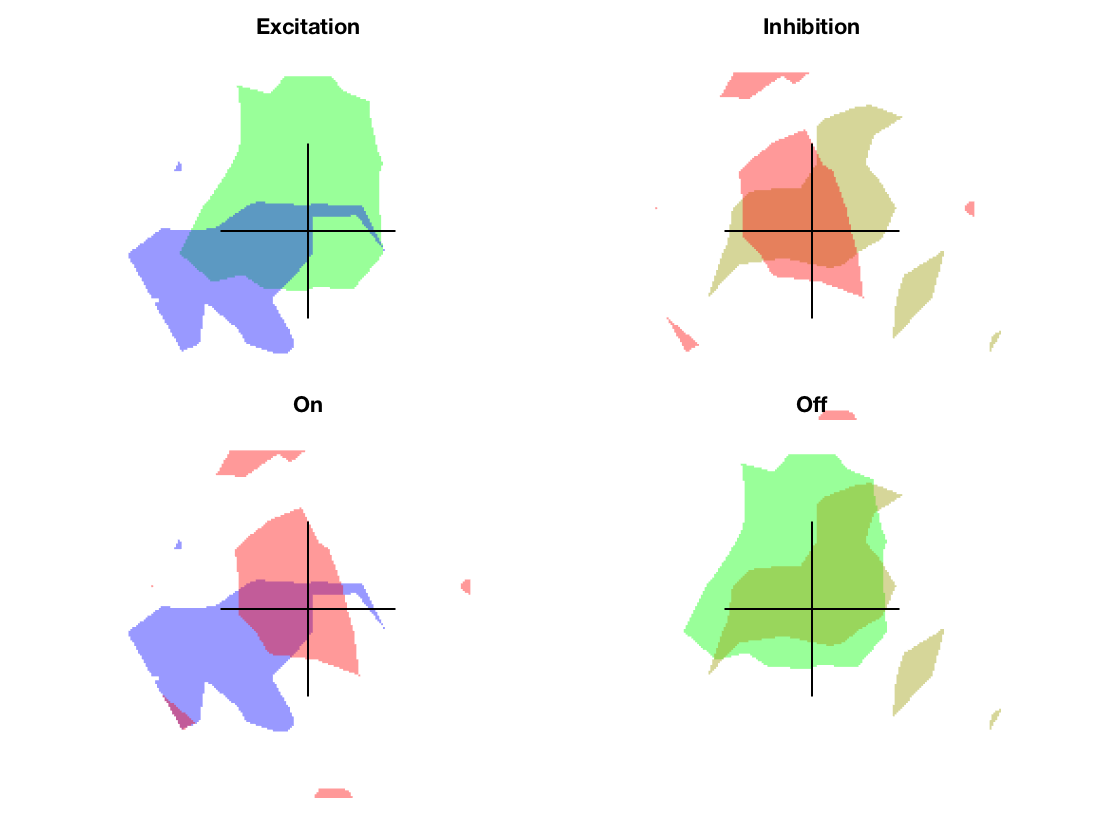

figure(17);clf;
options = struct();
options.overlapThresoldPercentile = 80;
plotShapeData(analysisData, 'overlap', options);

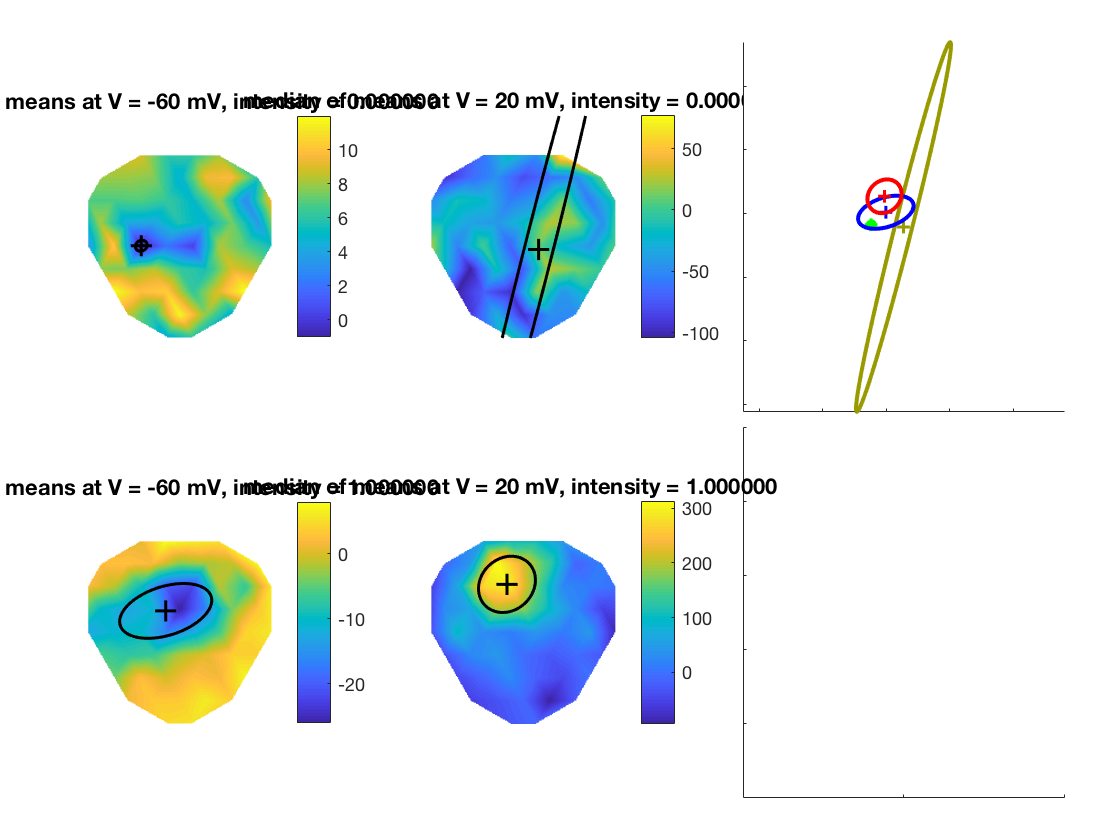

gaussian fit center: -24 um, -18 um
gaussian fit center: -1 um, 2 um
gaussian fit center: 27 um, -21 um
gaussian fit center: -3 um, 27 um


figure(18);clf;
plotShapeData(analysisData, 'plotSpatial_medianOfMeans')

## save maps

% plotShapeData(analysisData, 'plotSpatial_saveMaps');

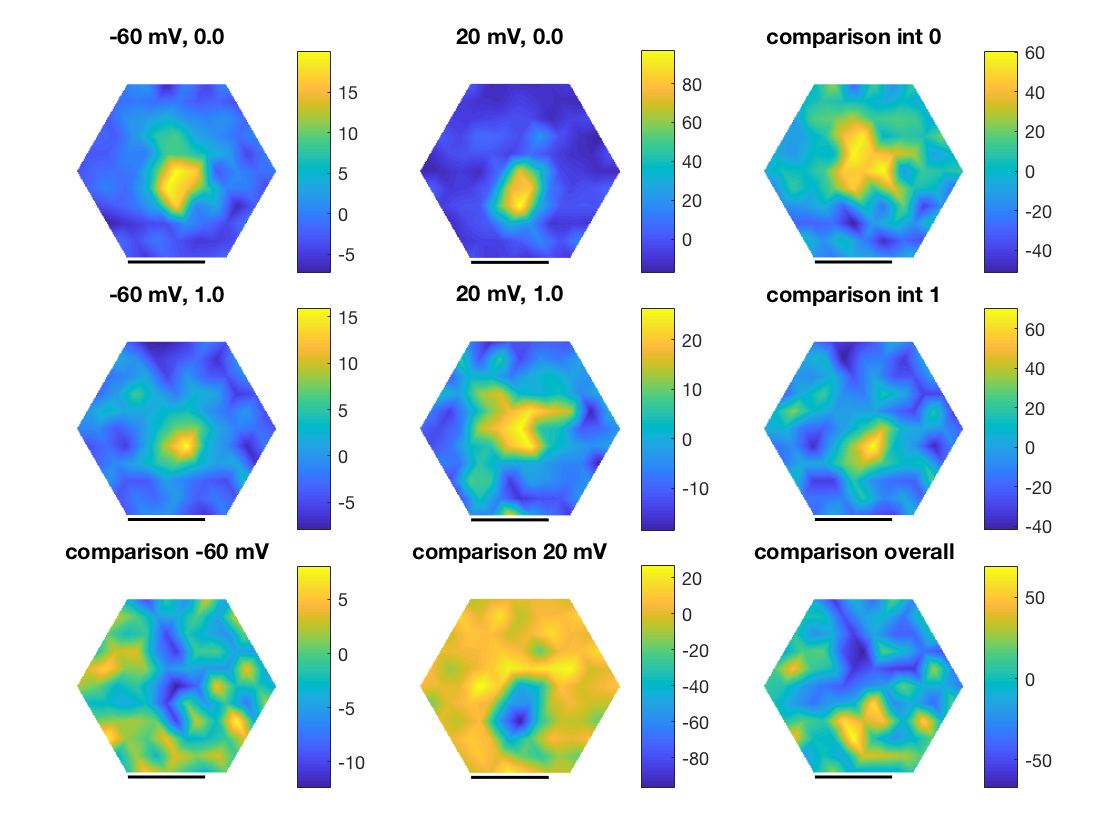

figure(201);clf;
plotShapeData(analysisData, 'wholeCell_comparisons')